# Nonlinear Robust Tracking Control of a Quadrotor UAV on SE(3)

Este trabajo proporciona sistemas de control de seguimiento no lineal para un vehículo aéreo no tripulado (UAV) cuadrotor que son robustos frente a incertidumbres acotadas. Se define un modelo matemático de un quadrotor UAV en el grupo euclidiano especial, y se desarrollan controladores no lineales de seguimiento de salida para seguir (i) una orden de actitud, y (ii) una orden de posición para el centro de masa del vehículo. El sistema controlado tiene las propiedades deseables de que los errores de seguimiento están uniformemente acotados en última instancia, y el tamaño del último límite puede reducirse arbitrariamente mediante parámetros del sistema de control. Se proporcionan ejemplos numéricos que ilustran maniobras complejas.

close all;
clc; clear;
addpath('./lib');
addpath('./src');

%% DEFINE
R2D = 180/pi;
D2R = pi/180;

## Modelo dinámico del Quadrotor

### Parametros

$\{ \vec{e_1},\vec{e_2},\vec{e_3} \} $                           $ \text{Conjunto de vectores unitaros que describen incercial-frame } \{A\}$.

$\{ \vec{b_1}, \vec{b_2},\vec{b_3}\}$                           $ \text{Conjunto de vectores unitarios que describen \textit{body-fixed }} \{B\}$.


$$m \in \mathbb{R}$$
                                 
$$\text{Masa total}$$



$$d \in \mathbb{R}$$
                                  
$$\text{Distancia del centro de masa al centro de cada motor en el pano}$$



$$J \in \mathbb{R}^{3 \times3}$$
                             
$$\text{Matriz de inercia con respecto al body-fixed frame} \{B\}$$



$$c_{\tau f} \in \mathbb{R}$$
                                
$$\text{Torque generado por la i-esima helice alrededor de } \vec{b_3}\\
\text{se puede escribir como } \tau_i = (-1)^1c_{tf}f_i \text{ para una constante fija }c_{tf}$$


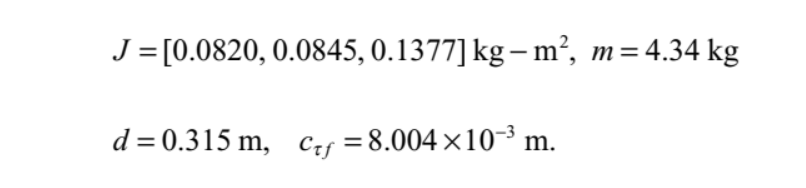

drone1_params = containers.Map({'mass','distance','Jxx','Jyy','Jzz'},...
    {4.34, 0.315, 0.082, 0.0845, 0.1377});


### Condiciones inciales


$$(x, v, R, \Omega)$$
                            
$$\text{Variables de estado}$$



$$x \in \mathbb{R}^3$$
                                 
$$\text{Vector de posición del centro de masa en el incertial-frame} \{A\}$$



$$v \in \mathbb{R}^3$$
                                 
$$\text{Vector de velocidad del centro de masa en el incertial-frame} \{A\}$$



$$R \in SO(3)$$
                           
$$ \text{Matriz de rotacion desde el body-fixed frame} \{B\} \text{ al inertial frame} \{A\} $$



$$\Omega \in \mathbb{R}^3 $$
                                
$$\text{Velocidad angular en body-fixed frame} \{ B \}$$
 

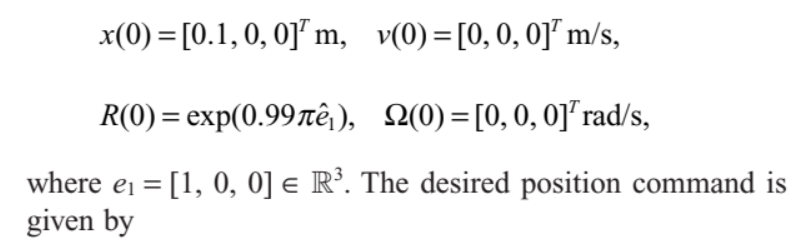

e_1 = [1, 0, 0]';

drone1_initStates = containers.Map({'position','velocity','angularV','SO(3)'}, ...
    {[0, -2, 8]',[0, 0, 0]', [0, 0, 0]', expm(0.99*pi*R2SO(e_1))});




$$f_i \in \mathbb{R}$$
                                  
$$\text{Empuje generado por las hélice i-ésima a lo largo del eje } -\vec{b_3}$$



$$\tau_i \in \mathbb{R} $$
                                 
$$\text{Torque generado por las hélice i-ésima a lo largo del eje } \vec{b_3}$$


### Entradas de control


$$f \in \mathbb{R}$$
                                 
$$\text{Magnitud de empuje total}$$
 
$$\sum_{i=1}^4 f_i$$



$$M \in \mathbb{R}^3$$
                              
$$\text{Vector de momento total en body-fixed frame } \{B\}$$


drone1_initInputs = [0, 0, 0, 0]';                                                                  

### Body-fixed frame

d = 0.315;
c_tf = 8.004*10^(-3);

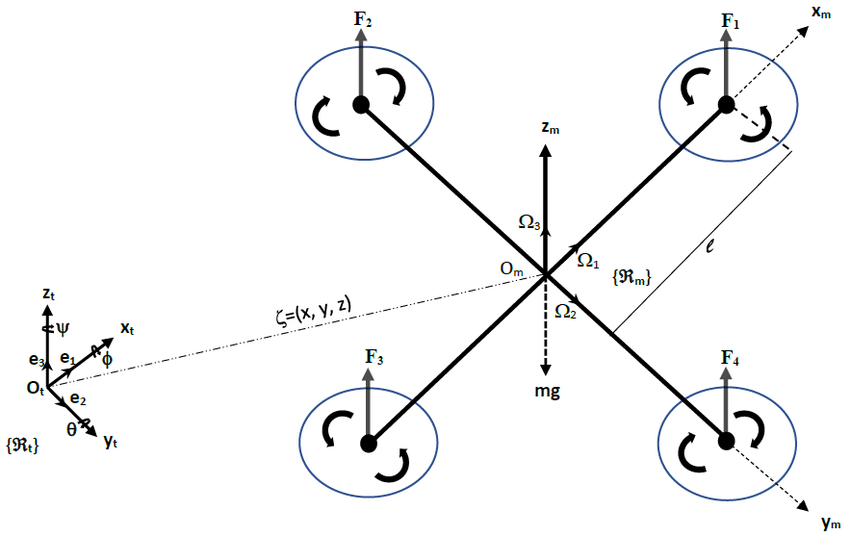


$$\left\lbrack \begin{array}{c}
f\\
M_1 \\
M_2 \\
M_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & 1 & 1 & 1\\
0 & -d & 0 & d\\
d & 0 & -d & 0\\
-c_{\tau f}  & -c_{\tau f}  & -c_{\tau f}  & -c_{\tau f} 
\end{array}\right\rbrack$$


drone1_body = [ d,     0,    -d,     0;
                0,    -d,     0,     d;
             -c_tf, -c_tf, -c_tf, -c_tf;
                1,     1,     1,     1;];

% drone1_body = [ 0.265,      0,     0, 1; ...
%                     0, -0.265,     0, 1; ...
%                -0.265,      0,     0, 1; ...
%                     0,  0.265,     0, 1; ...
%                     0,      0,     0, 1; ...
%                     0,      0, -0.15, 1]'

## Parametros de control

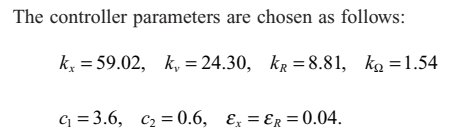


%% INIT PARAMCONTROL

drone1_controllerParam = containers.Map( ...
    {'k_x','k_v','k_R', 'k_Omega', 'c_1', 'c_2', 'epsilon_x', 'epsilon_R'}, ...
    {59.02, 24.3, 8.81, 1.54, 3.6, 0.6, 0.04, 0.04});



simulationTime = 5;                                                          % [sec]


### Asignacion de parametros

%% BIRTH OF A DRONE
drone1 = Drone(drone1_params, drone1_initStates, drone1_initInputs,drone1_controllerParam, simulationTime);



$$\dot{x} = v\\
m\dot{v} = mge_3 - fRe_3\\
\dot{R} = R \hat{\Omega}\\
J\dot{\Omega} + \Omega \times J\Omega = M $$


% EvalEOM(drone1)
% drone1.GetState


### Position Controlled Flight Mode



positionCommand = [0, 0, 0]';
drone1.PositionCtrlFM(positionCommand);

### Inicio de la simulacion

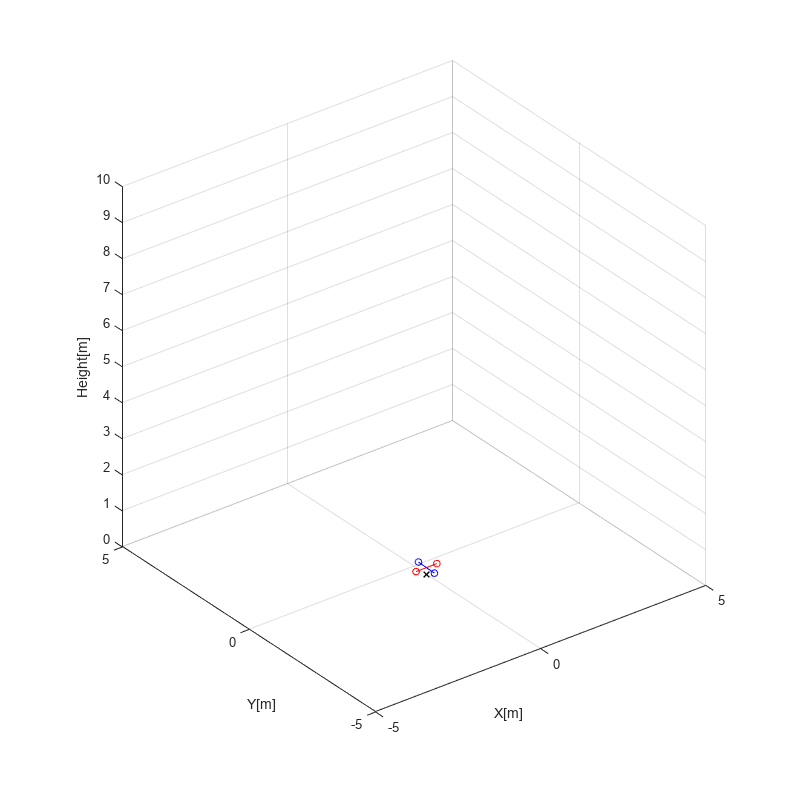

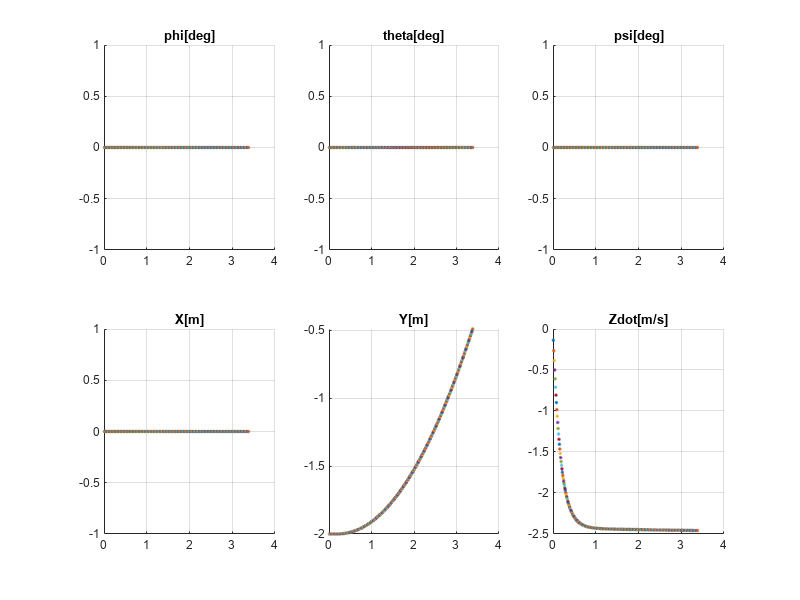

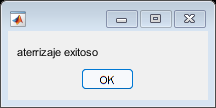

%% Init. 3D Fig.
fig1 = figure('pos',[0 200 800 800]);
h = gca;
view(3);


axis equal;
grid on;
xlim([-5 5]);
ylim([-5 5]);
zlim([0 10]);
xlabel('X[m]');
ylabel('Y[m]');
zlabel('Height[m]');


hold(gca, 'on');
drone1_state = drone1.GetState;
wHb = [drone1_state.R', drone1_state.s(1:3);
       0, 0, 0, 1];
drone1_word = wHb * drone1_body;
drone1_atti = drone1_word(1:3,:);
fig1_ARM13 = plot3(gca, drone1_atti(1,[1 3]), drone1_atti(2,[1 3]), drone1_atti(3,[1 3]), ...
        '-ro', 'MarkerSize', 5);
fig1_ARM24 = plot3(gca, drone1_atti(1,[2 4]), drone1_atti(2,[2 4]), drone1_atti(3,[2 4]), ...
        '-bo', 'MarkerSize', 5);

fig1_shadow = plot3(gca,0,0,0,'xk','Linewidth',1);

hold(gca, 'off');

%% Init. Data Fig.
fig2 = figure('pos',[800 400 800 600]);
subplot(2,3,1)
title('phi[deg]')
grid on;
hold on;
subplot(2,3,2)
title('theta[deg]')
grid on;
hold on;
subplot(2,3,3)
title('psi[deg]')
grid on;
hold on;
subplot(2,3,4)
title('X[m]')
grid on;
hold on;
subplot(2,3,5)
title('Y[m]')
grid on;
hold on;
subplot(2,3,6)
title('Zdot[m/s]')
grid on;
hold on;



%% Main Loop
positionCommand = [0, 0, 0]';




for i = 1:simulationTime/0.01
    %% Take a step
    drone1.PositionCtrlFM(positionCommand);
    drone1.UpdateState();
	
	drone1_state = drone1.GetState();
    
    %% 3D Plot
    figure(1)
    wHb = [drone1_state.R', drone1_state.s(1:3);
       0, 0, 0, 1];
    drone1_world = wHb * drone1_body;
    drone1_atti = drone1_world(1:3,:);

    set(fig1_ARM13, ...
        'XData', drone1_atti(1,[1 3]), ...
        'YData', drone1_atti(2,[1 3]), ...
        'ZData', drone1_atti(3,[1 3]));
    set(fig1_ARM24, ...
        'XData', drone1_atti(1,[2 4]), ...
        'YData', drone1_atti(2,[2 4]), ...
        'ZData', drone1_atti(3,[2 4])); 

	set(fig1_shadow, ...
		'XData', drone1_state.s(1), ...
		'YData', drone1_state.s(2));

     %% Data Plot
    figure(2)
    subplot(2,3,1)
        plot(i/100,drone1_state.s(7)*R2D,'.');
    subplot(2,3,2)
        plot(i/100,drone1_state.s(8)*R2D,'.');    
    subplot(2,3,3)
        plot(i/100,drone1_state.s(9)*R2D,'.');
    subplot(2,3,4)
        plot(i/100,drone1_state.s(1),'.');
    subplot(2,3,5)
        plot(i/100,drone1_state.s(2),'.');
    subplot(2,3,6)
        plot(i/100,drone1_state.s(6),'.');

    drawnow;

    if (drone1_state.s(3) <= 0.2)
        h = msgbox('aterrizaje exitoso');
        break;
    end

    
end